## **Driver test program to check Clothoids library**

**Test Intersection**

close all;

X = [2.9265642,2.6734362,2.5109322,1.9078122,1.1859282,1.9249962, ...
     2.8265562,0.00468420000000025,-2.826567,-1.9437558,-1.1859438, ...
     -1.9062558,-2.501565,-2.6734386,-2.9265642,-2.6187522,-1.1406318, ...
     -0.8968758,-1.4562558,-1.9062558,-0.00468780000000013,1.9078122, ...
     1.4468682,0.8968722,1.1406282,2.6187522, 2.9265642 ];
Y = [-1.707808758,-1.707808758,-2.367185958,-2.582810358,-2.582810358, ...
     -1.167184758,0.915619242,3.178123242,0.915619242,-1.150000758, ...
     -2.582810358,-2.582810358,-2.393750358,-1.707808758,-1.707808758, ...
     -3.178123242,-3.178123242,-2.989063158,-0.915616758,0.925003242, ...
     2.953123242,0.925003242,-0.915616758,-2.989063158,-3.178123242,-3.178123242, -1.707808758 ];


SG2 = ClothoidSplineG2();
S   = SG2.buildP2( X, Y );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         50.1412            58.3         0.01
     1           2        0.202802            6.29        0.001        1.73487
     2           3     8.47412e-07         0.00874       0.0001      0.0619425
     3           4     1.81744e-16        1.46e-07        1e-05    0.000199672
     4           5     3.10873e-27        2.28e-13        1e-06    5.92593e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<


S1 = ClothoidList();
S1.copy(S);
S1.rotate(pi,0,0);
S1.translate(0,-2);

S.rotate(pi/2,0,0);
S1.rotate(pi/2,0,0);

S1.plot();
hold on;
S.plot();

tic
[s1,s2] = S.intersect( S1 );  
toc

Elapsed time is 0.007818 seconds.


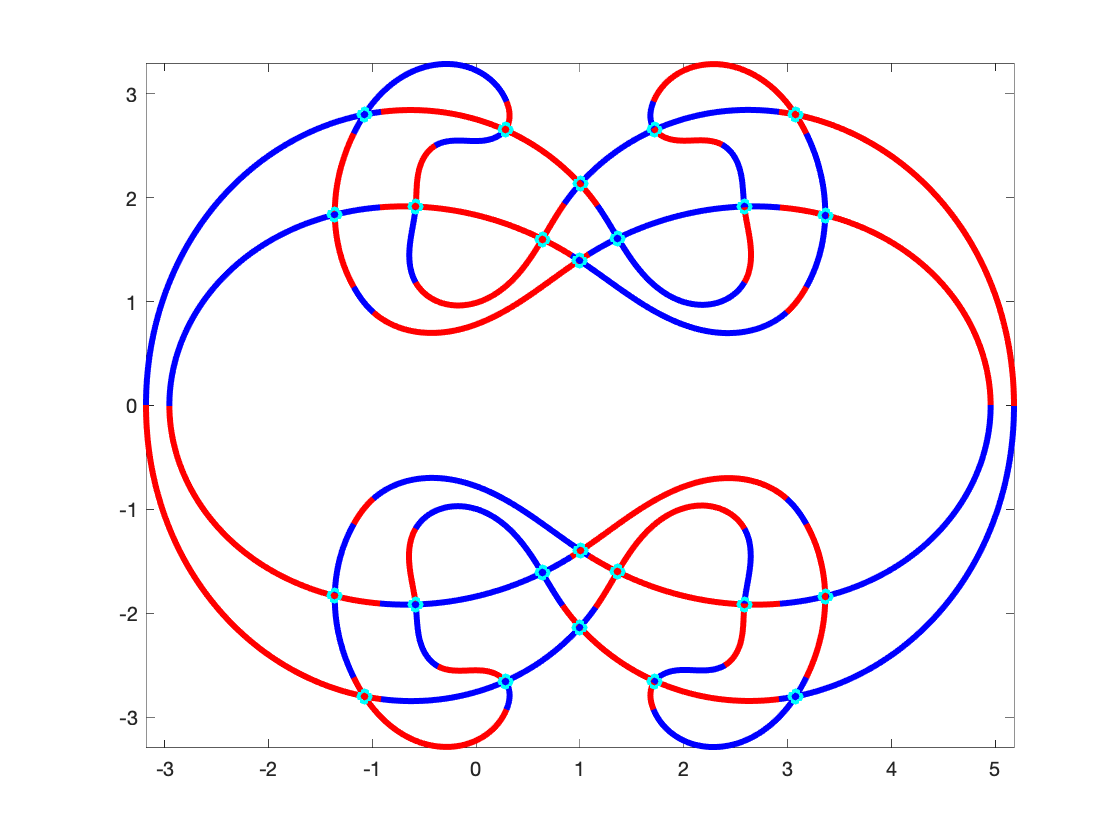


XY1 = S.eval( s1 );
XY2 = S1.eval( s2 );
  
if length(s1) > 0
 plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
end

if length(s2) > 0
  plot( XY2(1,:), XY2(2,:), 'oc', 'LineWidth', 2 );
end

axis equal